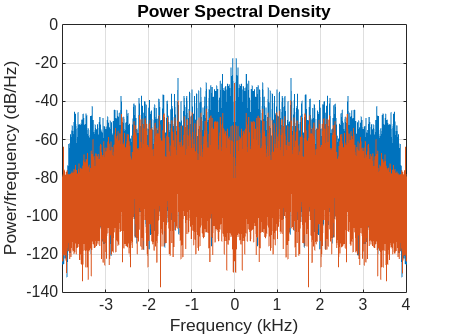

clear all;

[wav1, fs] = audioread("song1.wav");
figure;
hold on;
periodogram(wav1, [], [], fs, 'centered');
[wav4, fs] = audioread("sound32265398.wav");
periodogram(wav4, [], [], fs, 'centered');

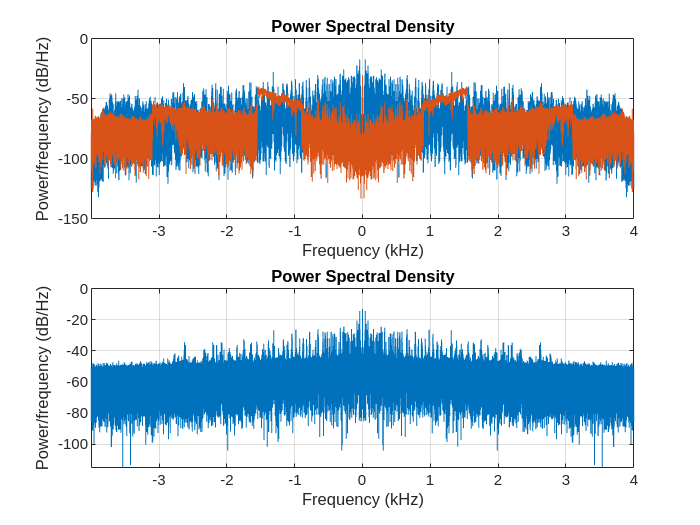

figure;
subplot(2, 1, 1);
hold on;
periodogram(wav1, [], [], fs, 'centered');
[wav6, fs] = audioread("sound19919663.wav");
periodogram(wav6, [], [], fs, 'centered');
hold off;
subplot(2, 1, 2);
[wav7, fs] = audioread("sound56184030_fm.wav");
periodogram(wav7, [], [], fs, 'centered');
hold off;

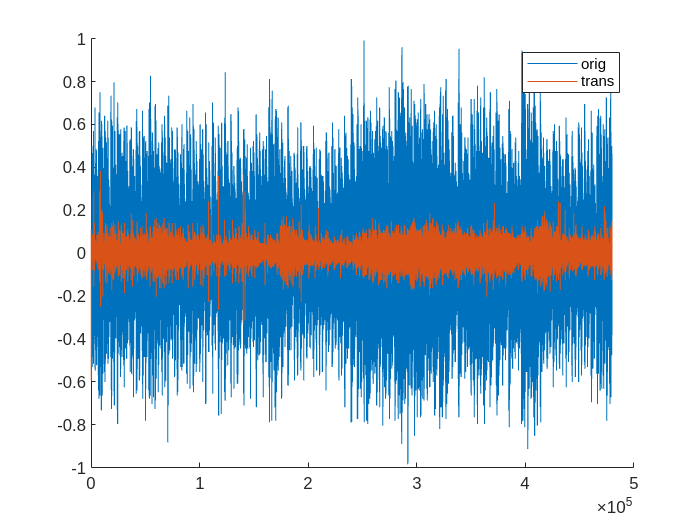

figure;
hold on;
plot(wav1);
plot(wav4);
legend('orig', 'trans');
hold off;

% Ex 1.3: 40dB
% Ex 1.5: Trans power: -10->0, Recv gain: 30->60

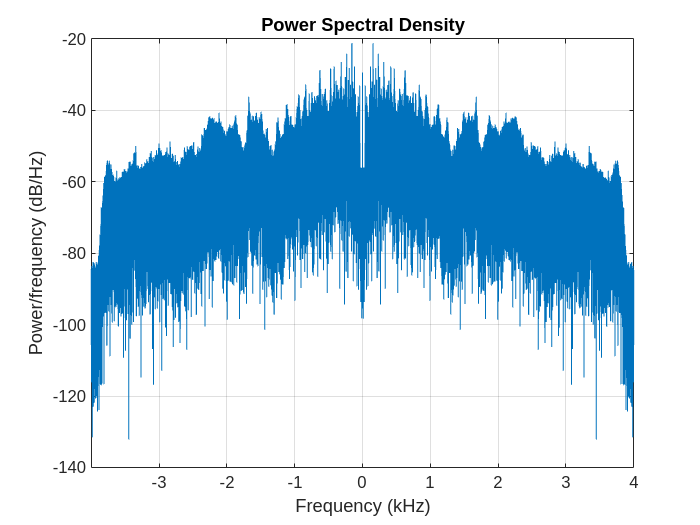

clear all;
[wav, fs] = audioread("song2.wav");
periodogram(wav, [], [], fs, 'centered');

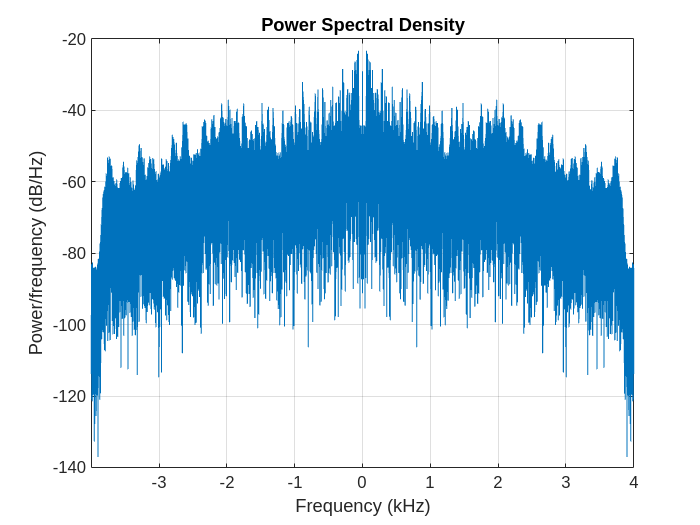

clear all;
[wav, fs] = audioread("song3.wav");
periodogram(wav, [], [], fs, 'centered');

N  = min(length(wav1),length(wav1));
x  = wav1(1:N);           % original, noise–free
y  = wav4(1:N);           % received / transmitted
e  = y - x;               % everything that is NOT the desired signal

SNR_out_dB = 20*log10( rms(x) / rms(e) );
fprintf('\nQuiz 1  →  SNR_out = %.1f dB\n',SNR_out_dB);


Quiz 1  →  SNR_out = -0.1 dB



noiseOnly      = wav6;                % <-- change here if needed

Unrecognized function or variable 'wav6'.

P_lin          = mean(noiseOnly.^2);  % average power (linear, 1-Ω load)
P_dBm          = 10*log10(P_lin/1e-3);
fprintf('\nQuiz 2  →  Noise floor = %.0f dBm\n',P_dBm);


rx          = wav6;        % <-- put baseband AM here if different
gains       = 10:10:200;   % test ×10, ×20, … ×200 (extend if necessary)
peaks       = zeros(size(gains));

for k = 1:numel(gains)
    test         = gains(k)*rx;
    peaks(k)     = max(abs(test));
end

% look for the first gain where further increase does not raise the peak
dPeak        = diff(peaks);
thresh       = 1e-4;                       % adjust if your data is noisy
idx          = find(dPeak < thresh,1,'first');

if isempty(idx)           % never hit the limit – take last value tested
    maxGain   = gains(end);
else
    maxGain   = gains(idx);
end

% Quiz wants the value as a “multiple of 10”, i.e. print 60 not 6 or 0.6 dB
fprintf('\nQuiz 5  →  Maximum receiver gain = %d\n',maxGain);